# cwEDMR analysis for reverse bias 1V under illumination

clearvars, close all

## Import

files0deg = dir('*_0Deg_Light.DTA');
files90deg = dir('*_90Deg_Light.DTA');
data = struct();

for i=1:length(files0deg)
    [data(i).B, data(i).spc, data(i).Params] = ...
        eprloadQuad(files0deg(i).name, files90deg(i).name);
    % Field offset (obtained from 013_calibration_NC60 in this same folder)
    % and conversion to mT
    data(i).B = (data(i).B - 5.181)/10; 
    newStr = strsplit(files0deg(i).name, '_');
    data(i).title = newStr(5);
end

## Baseline correction

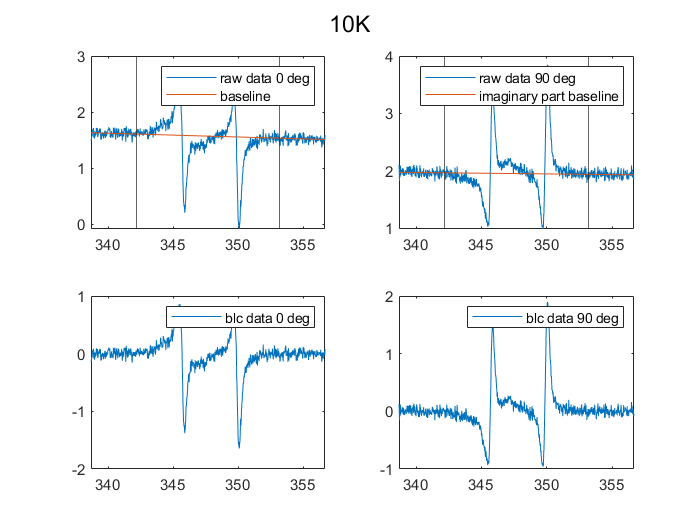

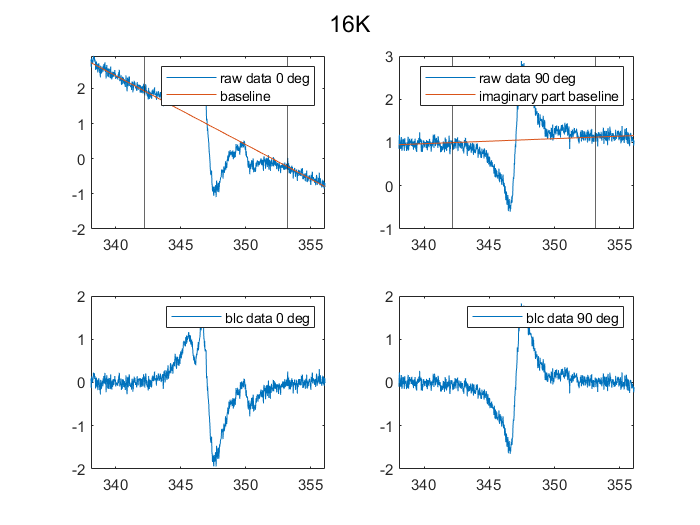

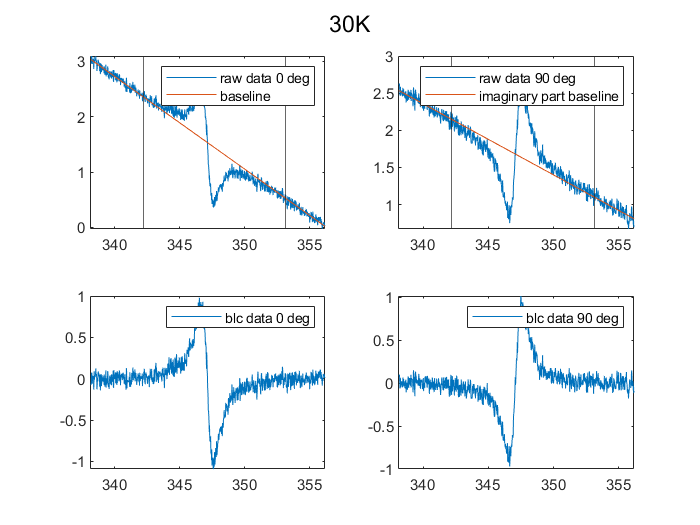

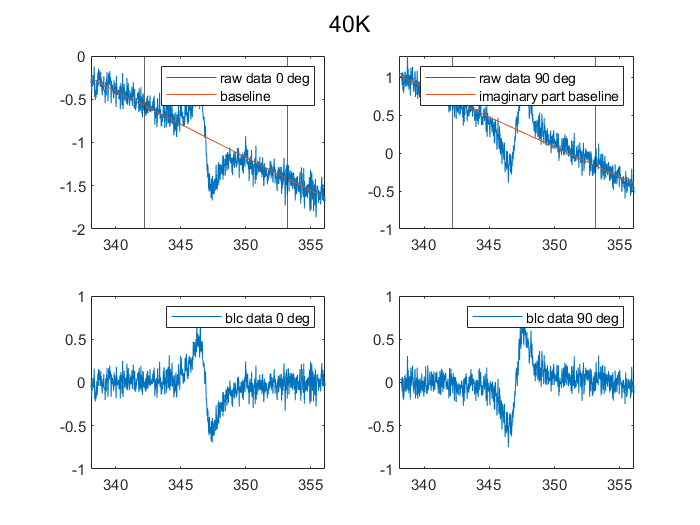

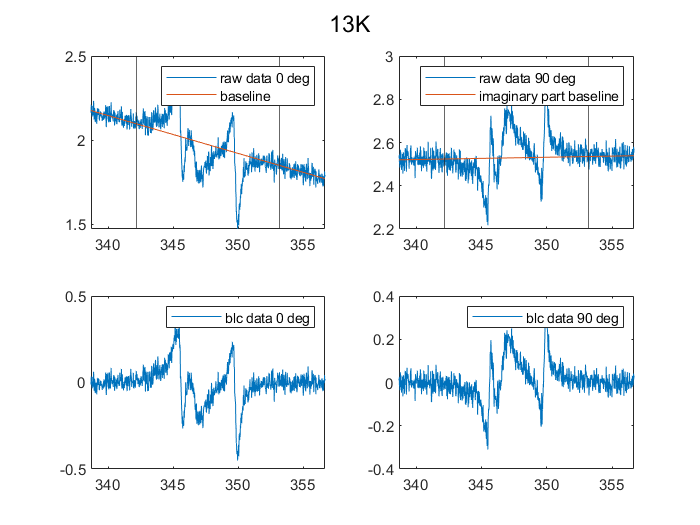

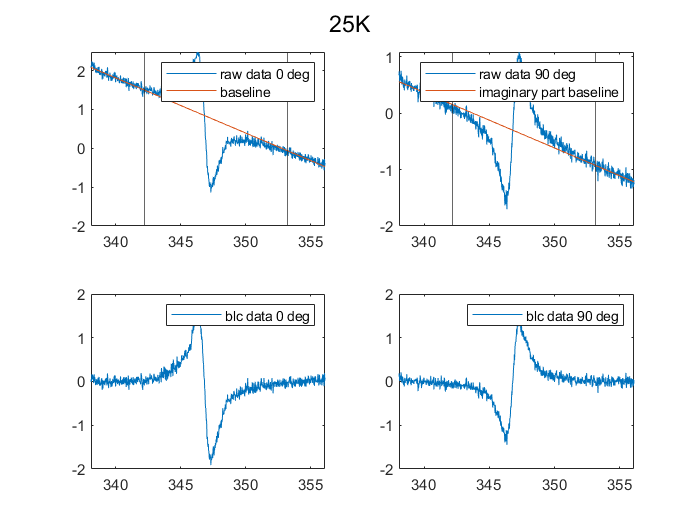

% Opt.range is the left range, Opt.range1 is the right one. The resonance
% peak should be in between these two ranges.
Opt.range = [1, 200];
Opt.range1 = [numel(data(1).B) - 200, numel(data(1).B)];
Opt.order = 1;

for i=1:length(files0deg)
    [data(i).blc, data(i).bl] = ...
        baselineSubtractionPolyfit(data(i).B, data(i).spc, Opt);
    
    figure(i)
    subplot(2,2,1)
    plot(data(i).B, real(data(i).spc), data(i).B, real(data(i).bl))
    xline(data(1).B(Opt.range(2))) % Here using data(1) because the range was defined through that one
    xline(data(1).B(Opt.range1(1)))
    xlim([min(data(i).B) max(data(i).B)])
    legend('raw data 0 deg', 'baseline')
    
    subplot(2,2,3)
    plot(data(i).B, real(data(i).blc))
    xlim([min(data(i).B) max(data(i).B)])
    legend('blc data 0 deg')
    
    subplot(2,2,2)
    plot(data(i).B, imag(data(i).spc), data(i).B, imag(data(i).bl))
    xline(data(1).B(Opt.range(2)))
    xline(data(1).B(Opt.range1(1)))
    xlim([min(data(i).B) max(data(i).B)])
    legend('raw data 90 deg', 'imaginary part baseline')
    
    subplot(2,2,4)
    plot(data(i).B, imag(data(i).blc))
    xlim([min(data(i).B) max(data(i).B)])
    legend('blc data 90 deg')
    sgtitle(data(i).title)
end

## Phase correction

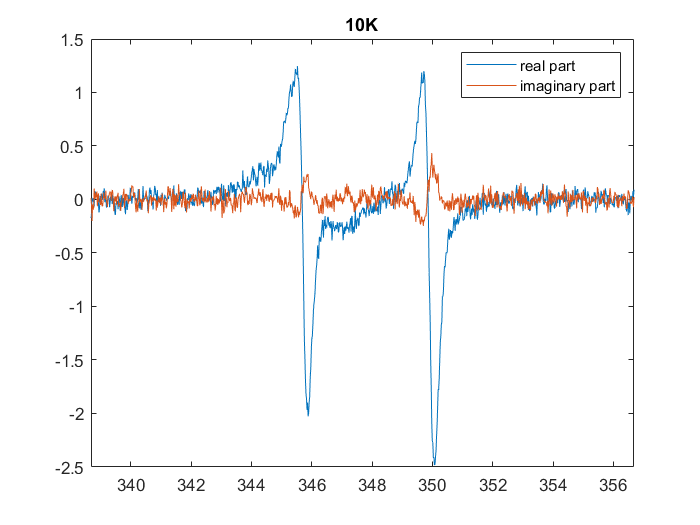

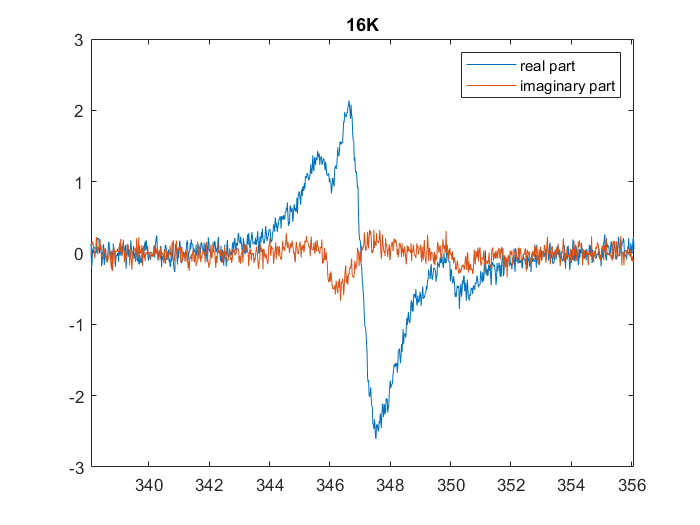

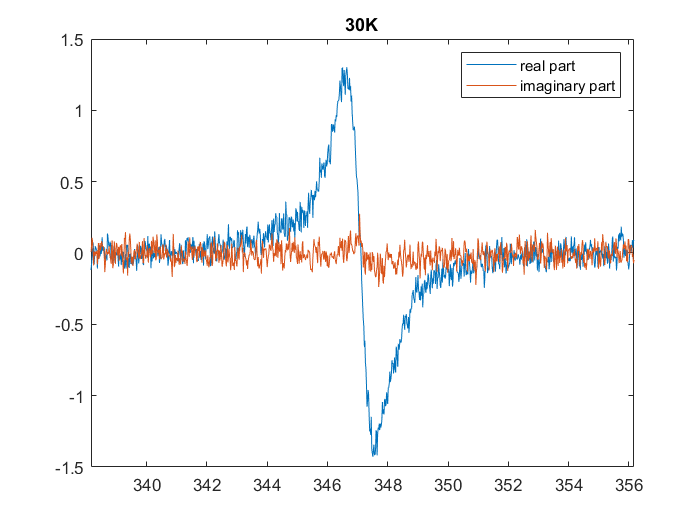

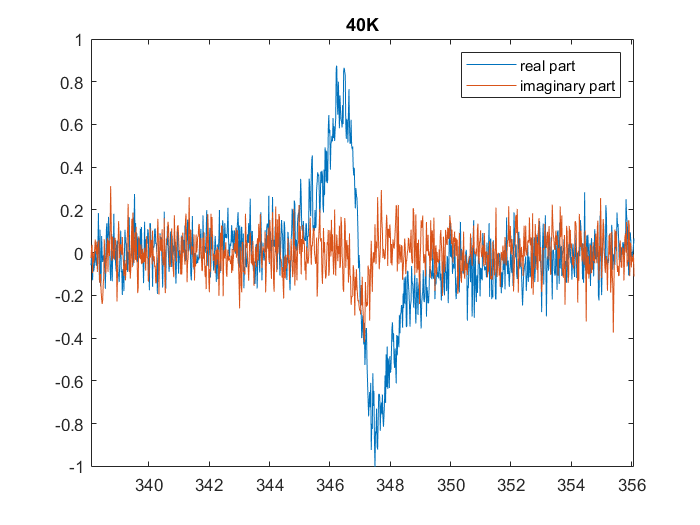

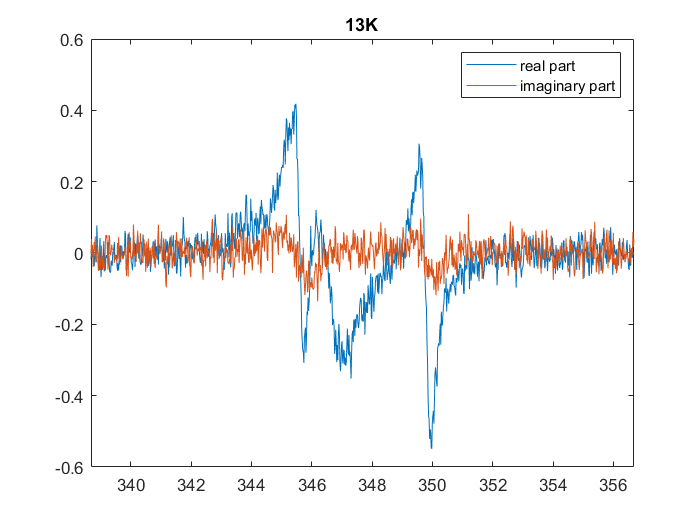

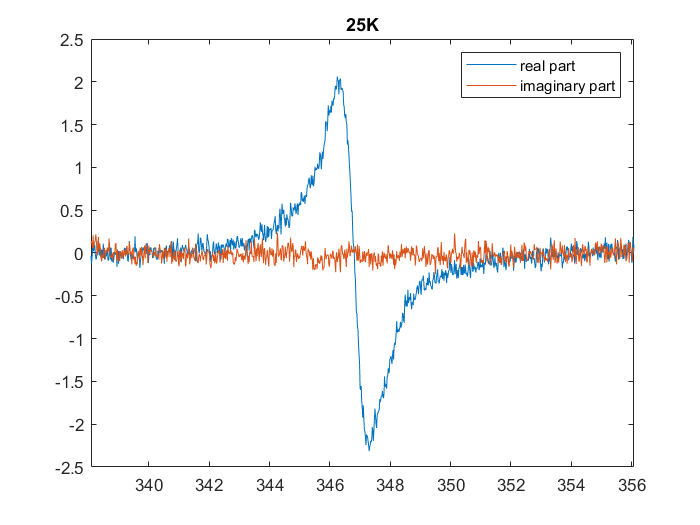

for i=1:length(files0deg)
    [data(i).spcFinalComplex, data(i).phase] = correctPhase(data(i).blc);
    data(i).spcFinal = real(data(i).spcFinalComplex);
    
    figure()
    plot(data(i).B, real(data(i).spcFinalComplex), data(i).B, imag(data(i).spcFinalComplex))
    xlim([min(data(i).B) max(data(i).B)])
    legend('real part', 'imaginary part')
    title(data(i).title)
end

## Nice looking plots

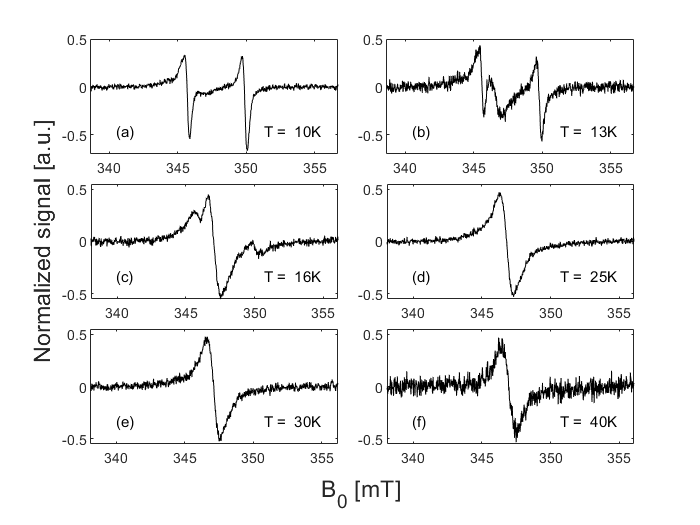

fig = figure();
t = tiledlayout(3,2);
t.TileSpacing = 'compact';

nexttile;
i = 1;
plot(data(i).B, ...
    data(i).spcFinal/(max(data(i).spcFinal) - min(data(i).spcFinal)), 'k');
xlim([min(data(i).B) max(data(i).B)]);
ylim([-0.7 0.5]);
text(.1, .2, '(a)', 'FontSize', 9, 'Units', "normalized");
text1 = strjoin(['T = ' data(i).title]);
text(.7, .2, text1, 'FontSize', 9, 'Units', "normalized");

nexttile;
i = 5;
plot(data(i).B, ...
    data(i).spcFinal/(max(data(i).spcFinal) - min(data(i).spcFinal)), 'k');
xlim([min(data(i).B) max(data(i).B)]);
ylim([-0.7 0.5]);
text(.1, .2, '(b)', 'FontSize', 9, 'Units', "normalized");
text1 = strjoin(['T = ' data(i).title]);
text(.7, .2, text1, 'FontSize', 9, 'Units', "normalized");

nexttile;
i = 2;
plot(data(i).B, ...
    data(i).spcFinal/(max(data(i).spcFinal) - min(data(i).spcFinal)), 'k');
xlim([min(data(i).B) max(data(i).B)]);
ylim([-0.55 0.55]);
text(.1, .2, '(c)', 'FontSize', 9, 'Units', "normalized");
text1 = strjoin(['T = ' data(i).title]);
text(.7, .2, text1, 'FontSize', 9, 'Units', "normalized");

nexttile;
i = 6;
plot(data(i).B, ...
    data(i).spcFinal/(max(data(i).spcFinal) - min(data(i).spcFinal)), 'k');
xlim([min(data(i).B) max(data(i).B)]);
ylim([-0.55 0.55]);
text(.1, .2, '(d)', 'FontSize', 9, 'Units', "normalized");
text1 = strjoin(['T = ' data(i).title]);
text(.7, .2, text1, 'FontSize', 9, 'Units', "normalized");

nexttile;
i = 3;
plot(data(i).B, ...
    data(i).spcFinal/(max(data(i).spcFinal) - min(data(i).spcFinal)), 'k');
xlim([min(data(i).B) max(data(i).B)]);
ylim([-0.55 0.55]);
text(.1, .2, '(e)', 'FontSize', 9, 'Units', "normalized");
text1 = strjoin(['T = ' data(i).title]);
text(.7, .2, text1, 'FontSize', 9, 'Units', "normalized");

nexttile;
i = 4;
plot(data(i).B, ...
    data(i).spcFinal/(max(data(i).spcFinal) - min(data(i).spcFinal)), 'k');
xlim([min(data(i).B) max(data(i).B)]);
ylim([-0.55 0.55]);
text(.1, .2, '(f)', 'FontSize', 9, 'Units', "normalized");
text1 = strjoin(['T = ' data(i).title]);
text(.7, .2, text1, 'FontSize', 9, 'Units', "normalized");

% Common labels
xlabel(t, 'B_0 [mT]', 'FontSize', 14);
ylabel(t, 'Normalized signal [a.u.]', 'FontSize', 14);
% saveas(gcf, 'cw_Tdependence', 'pdf')

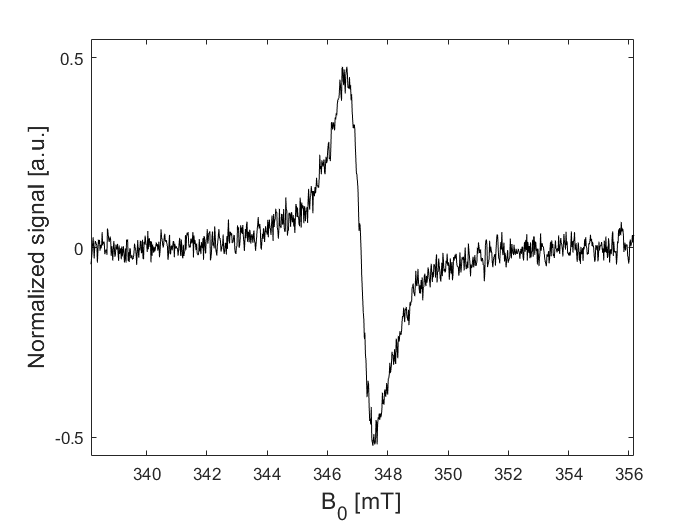

fig = figure();
i = 3;
plot(data(i).B, ...
    data(i).spcFinal/(max(data(i).spcFinal) - min(data(i).spcFinal)), 'k');
xlim([min(data(i).B) max(data(i).B)]);
ylim([-0.55 0.55]);
yticks([-0.5, 0, 0.5])
xlabel('B_0 [mT]', 'FontSize', 14);
ylabel('Normalized signal [a.u.]', 'FontSize', 14);

% saveas(fig, 'cw_30K', 'pdf')

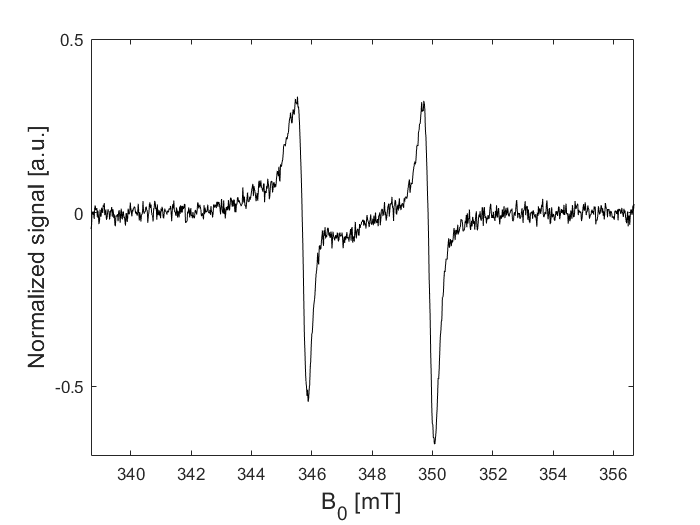

fig = figure();
i = 1;
plot(data(i).B, ...
    data(i).spcFinal/(max(data(i).spcFinal) - min(data(i).spcFinal)), 'k');
xlim([min(data(i).B) max(data(i).B)]);
ylim([-0.7 0.5]);
yticks([-0.5, 0, 0.5])
xlabel('B_0 [mT]', 'FontSize', 14);
ylabel('Normalized signal [a.u.]', 'FontSize', 14);

% saveas(fig, 'cw_10K', 'pdf')

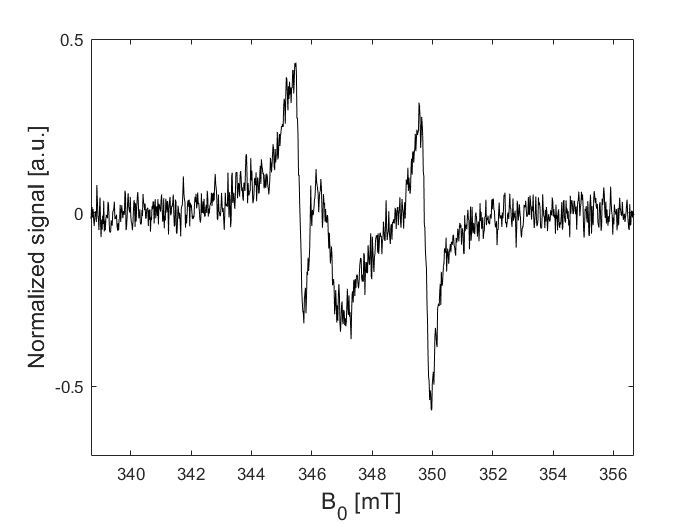

fig = figure();
i = 5;
plot(data(i).B, ...
    data(i).spcFinal/(max(data(i).spcFinal) - min(data(i).spcFinal)), 'k');
xlim([min(data(i).B) max(data(i).B)]);
ylim([-0.7 0.5]);
yticks([-0.5, 0, 0.5])
xlabel('B_0 [mT]', 'FontSize', 14);
ylabel('Normalized signal [a.u.]', 'FontSize', 14);
% saveas(fig, 'cw_13K', 'svg')